# COUNTING MODEL

A robot applies the so-called simple counting approach to build a grid map of a 1D environment consisting of the cells c0: ... : c3. While standing in cell c0, the robot integrates four measurements zt0 : ... : zt3 . After integrating these measurements, the resulting belief of the robot with regards to the occupancy of the four cells is b0 = 0; b1 = 1/4 ; b2 = 2/3 ; b3 = 1. Given that the first three measurements are zt0 = 1; zt1 = 2; zt2 = 3, compute the value of the last measurement zt3 .

Occupancy Mapping estimation given data 

This calculates a map based on the simple counting method The probability is calculated by the following: bel(m[x]) = hits / ( hits + misses ) Hits are defined as the number of measurements that land exactly on the given square misses are defined as the number of measurements that pass through a given square

% One dimensional example with 6 possible cells in map
% MAP
c = zeros(1,6);

% Robot standing in square 1
pos = 1;

% Measurements
z = [1 2 3 0];

% Calculate Map Occupancy, cell by cell
h = z

h =      1     2     3     0


h(pos) = 0

h =      0     2     3     0


for i=1:length(h)
    h(i) = sum(h())
    m(i) = sum(h(i:4))
    c(i) = h(i) / (h(i) + m(i))
end

m =      5     8     6     3


c =      0     0     0     0     0     0


m =      5     5     6     3


c =          0    0.2857         0         0         0         0


m =      5     5     3     3


c =          0    0.2857    0.5000         0         0         0


m =      5     5     3     0


c =          0    0.2857    0.5000       NaN         0         0


% Display the correct beliefs 
c = h ./ (h+m)

c =          0    0.2857    0.5000       NaN


## Occupancy Mapping

A robot has to build an occupancy grid map (cells c0: ... : cn) of a simple onedimensional environment using a sequence of measurements from a range sensor.

Assume a very simple sensor model: every grid cell with a distance (based on its coordinate) smaller than the measured distance is assumed to be occupied with p = 0.3. Every cell behind the measured distance is occupied with p = 0.6. Every cell located more than 20cm behind the measured distance should not be updated. Calculate the resulting occupancy grid map using the inverse sensor model

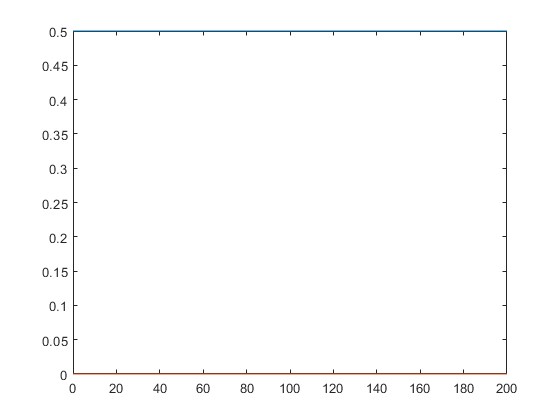

%Sidenote l(x) = log(p(x)/1-p(x))

% Measurements
z = [101, 82, 91, 112, 99, 151, 96, 85, 99, 105];

% Cell Coordinates
c=[0:5:200];

% Map Start Beliefs p=0.5
map = 0.5*ones(size(c));
mapln = zeros(size(c));

% Additional assumption: Map is static

% Calculate the probability that a map square is occupied based on given
% measurements.  Perform the calculations twice.  Once in a linear form,
% the second in logarithmic, and overlay the two answers on one graph

hold off

plot(c,map)
hold on
plot(c,mapln)